## Exercise 1.3.

*Consider the linear system of equations*

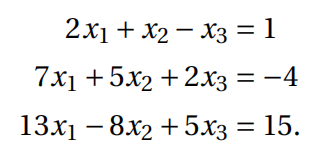

*Enter this system of equations in matrix representation and calculate the solution vector *`x ``=``[``x``1,``x``2,``x``3]``T` *with *`x``1,``x``2` *and *`x``3` *in fraction representation. To solve the system of equations, make first use of the *`inv()` *command and secondly consider with the *`mldivide()` *command (or in its short form *`\`*). How do these commands differ and when should which be used?*

## *Answer*

% Rewrite in matrix representation
A = [2,1,-1; 7,5,2; 13,-8,5]

A =      2     1    -1
     7     5     2
    13    -8     5


B = [1; -4; 15]

B =      1
    -4
    15



format RATIONAL % represent in fraction format

tic
% Calculate matrix X: [x1;x2;x3]
X = inv(A) * B

X =       67/97    
    -133/97    
     -96/97    


toc

Elapsed time is 0.013737 seconds.



tic
% Check the function of backslash-operator "\"
clear X
X = A\B

X =       67/97    
    -133/97    
     -96/97    


toc 

Elapsed time is 0.022740 seconds.



format long g
A = randn(5,5); 
b = randn(5,1);
x = A\b

x =          -3.38716529563646
       -0.0913978905360386
          3.36189387514132
         0.571825863114837
           3.0559865014612


y = inv(A)*b

y =          -3.38716529563646
       -0.0913978905360387
          3.36189387514132
         0.571825863114837
           3.0559865014612


x-y

ans =                          0
      1.38777878078145e-16
      4.44089209850063e-16
     -1.11022302462516e-16
      4.44089209850063e-16



A = rand(3,4); % an over-determined system
b = rand(3,1);
A\b

ans =                          0
          4.28674542365188
         0.491235032211965
         -5.53698215006319


inv(A)*b

Error using inv
Matrix must be square.

## *Analysis*

The backslash-operator solves the system of linear equations: `A *X = B`. 

If we however measure the time taken for each approach, it can be seen that the backslash operator is faster than the basic process of getting the inverse of `A2` first and then multiply its inverse with `B2`.

The backslash-operator can solve an overdetermined system ( when the matrix is not a square matrix )

If the matrix is close to being singular, the backslash operator provides more accurate results

Therefore, `mldivide()` is recommended for solving systems of linear equations.